# BPM Calculations by Windows

Calculate the BPM for each consecutive window

## Sound Data and Window Parameters

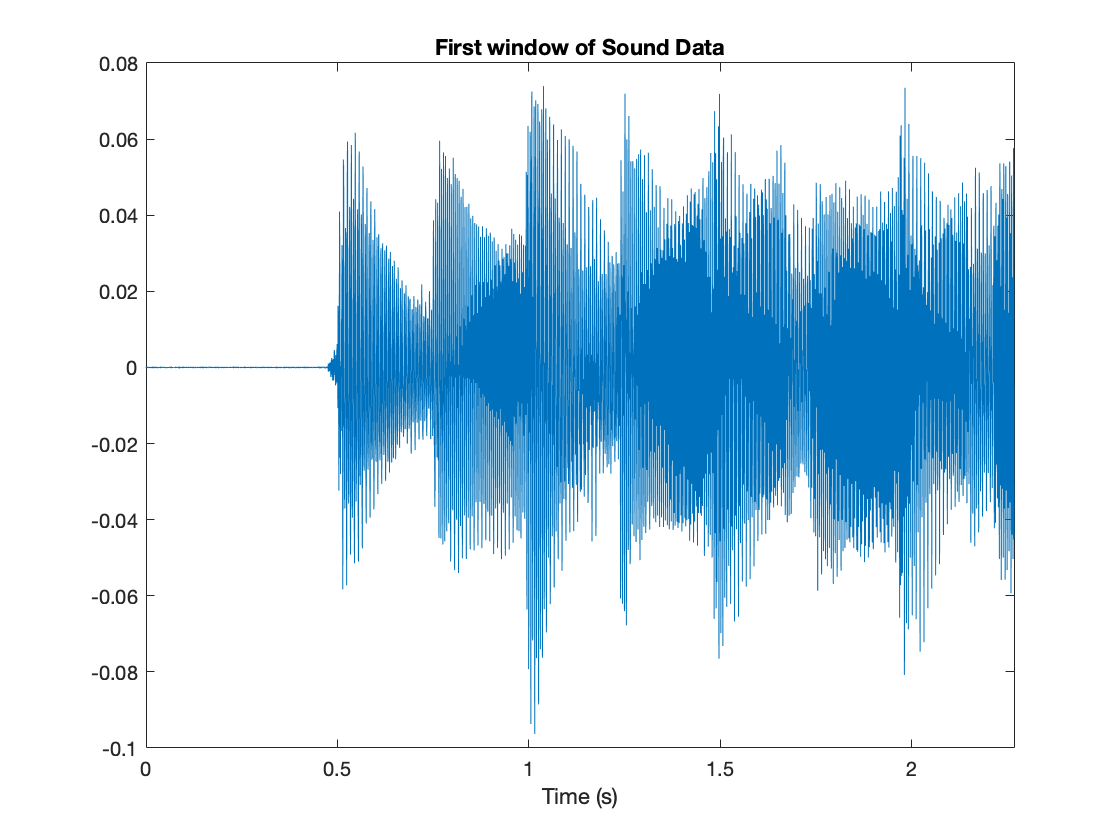

%Import sound data
% In the case of live streaming, a buffer will be filled
% and once the first buffer has been filled, the first window 
% will be processed

%track_name = 'fortroad_lost.wav';
%track_name = 'heybrother_avicii.wav';
track_name = 'Avicii - Hey Brother.wav';
%track_name = 'fortroad_lost 3.wav';
[x fs]=audioread(track_name);

%Create a time index
t=0:1/fs:(length(x)-1)/fs;

%Set parameters for windows
samples = 100000; % Number of samples per window (must be greater than 4000)
duration = samples/fs; % Duration in seconds
starti = 1; % Starting index
start_time=(starti-1)/fs; % start time in seconds
finishi = starti + samples;
finish_time=(finishi-1)/fs;

xwindow=x(starti:finishi);
twindow = t(starti:finishi);

figure
plot(twindow,xwindow)
xlim([start_time finish_time])
xlabel("Time (s)");
title("First window of Sound Data");

## BPM Measurements

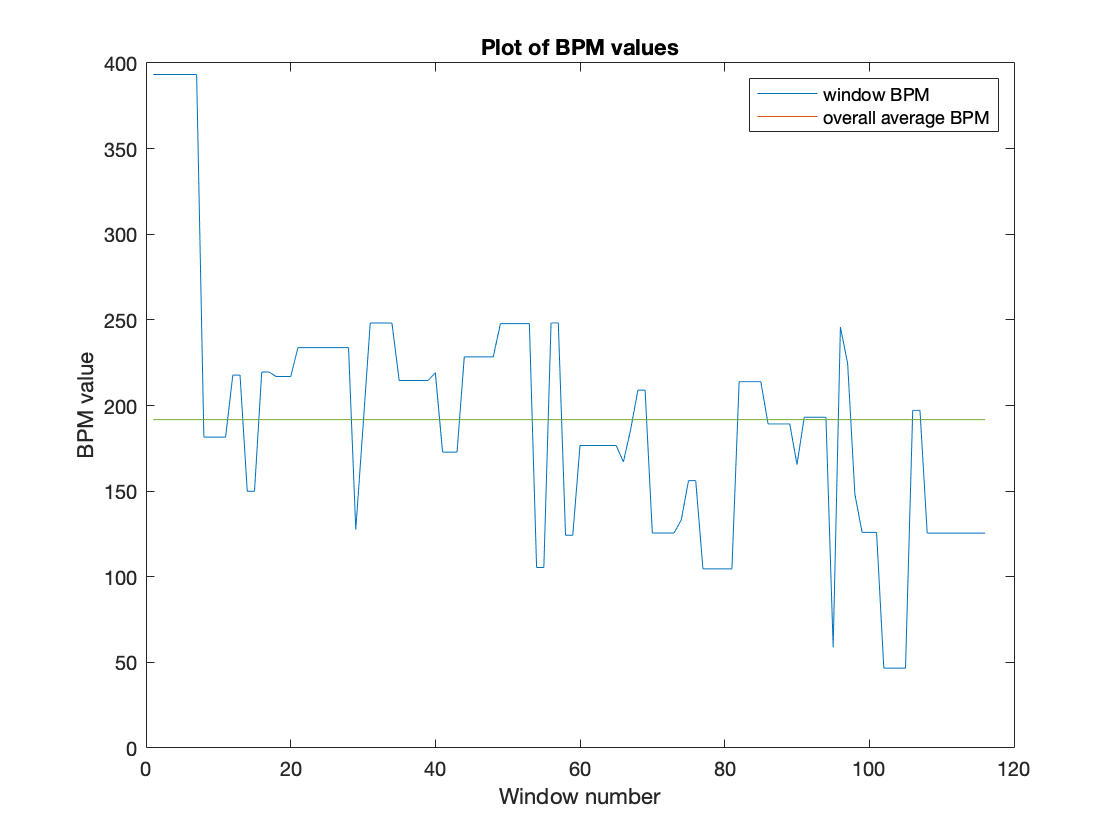

BPMvalues=[]; % Array to store calculated BPMs
BPMindex=1;

% Calculate BPM values for the different windows
for i=starti:samples:(length(x)-1-samples)
    finishi = i + samples;
    xwindow=x(i:finishi);
    BPM = calculateBPM(xwindow,fs);
    BPMvalues(BPMindex)=BPM;
    BPMindex=BPMindex+1;
end

% Disgard BPM values that do not meet realistic constrains
%BPMvalues(BPMvalues>250)=[];
%BPMvalues(isnan(BPMvalues))=[]; % Remove invalid times

% ??? Some BPM values obtained are abnormal
% Correct BPM values that do not meet realistic constraints
% or are invalid (set equal to previous value?)
for j=2:length(BPMvalues)
    if (BPMvalues(j)>250 | isnan(BPMvalues(j)))
        BPMvalues(j)=BPMvalues(j-1);
    end
end

% Calculate the overall average BPM
meanBPM=mean(BPMvalues);

figure
plot(BPMvalues)
hold on
xlabel("Window number")
ylabel("BPM value")
title("Plot of BPM values")
plot(meanBPM.*ones(length(BPMvalues)))
hold off
legend("window BPM", "overall average BPM");

## BPM and Moving Average Power

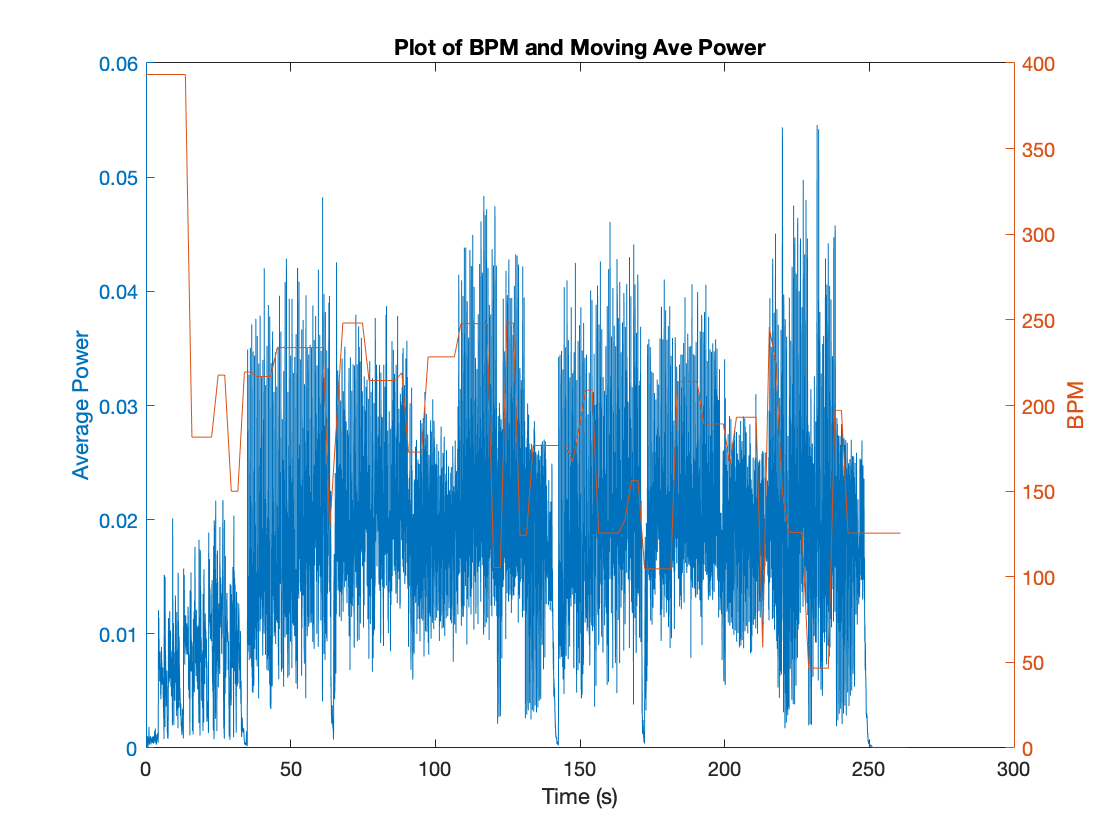

% Plot calculated BPM on sound data

p = movmean(x.^2, 2000);

tBPM=0:samples/fs:(length(BPMvalues)*samples-1)/fs;
figure
yyaxis right
plot(tBPM, BPMvalues)
ylabel("BPM")
yyaxis left
plot(t,p)
ylabel("Average Power")
xlabel("Time (s)")
title("Plot of BPM and Moving Ave Power")

## Functions

% BPM calculation function

function BPM = calculateBPM(xwindow, fs)
    % Find moving average power
    pwindow = movmean(xwindow.^2, 2000);
    %Perform auto-correlation on the moving ave power
    acpwindow = xcorr(pwindow);
    % Discard second (symmetric) half and first 100 samples
    acpwindowHalf=acpwindow(100:round(length(acpwindow)/2));
    %tACF2=0:1/fs:(length(acpwindowHalf)-1)/fs;
    
    % CALCULATE BPM
    % Find peaks and corresponding times
    [pks,times] = findpeaks(acpwindowHalf,fs);
    % Remove invalid peaks
    for i=2:length(pks)
        % If the value of the peak is less than the previous
        % peak, remove its time
        if pks(i)<pks(i-1)
            times(i)=0; % Set time to zero and remove later
            pks(i)=pks(i-1);
        end
    end
    times(times==0)=[]; % Remove invalid times
    
    timeDifference=mean(diff(times)); % Get the time difference between the peaks
    BPM=(1/timeDifference)*60;
    %disp("BPM calculated -> " + BPM)
    
end